# Script04＿Simulinkによる状態平均化モデルとSimscapeの電気回路モデルの比較

Copyright (c) 2022, The MathWorks, Inc.All rights reserved.

Simulinkによる状態平均化モデルはコンバータが持つ各状態やパラメータの関係性が理解しやすい

理論ベースの式であるため、制御設計において有効である。

一方で回路設計者にとっては回路図ベースの電気回路シミュレーションモデルのほうが回路の状態を理解しやすい。

このように、立場の違う設計者同士では自分自身の業務や理解にとって都合のよいモデルを使う傾向にあるが、

この両者で別のツールを用いていると設計情報の一致性やシミュレーションモデルの粒度の違いについて議論する際に

共通の環境下で比較検討が行えず、設計の反映漏れや互いに意思疎通の齟齬による設計ミスが発生し

設計のあと段階で発覚してしまうことが起こる可能性がある。

このスクリプトでは

**理論ベース式である状態平均化モデルと回路シミュレータモデルが**

**共存できる環境を構築し、両者に同じ信号を入力した際の出力を比較することを示す。**

**このような環境は、両モデルが持つパラメータや、抽象度の違いが**

**シミュレーション出力にどのように影響をおよぼすかを理解する手助けになる。**

## 0.モデルを用意する

検討として下記モデルを用いる。

open_system("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");

## 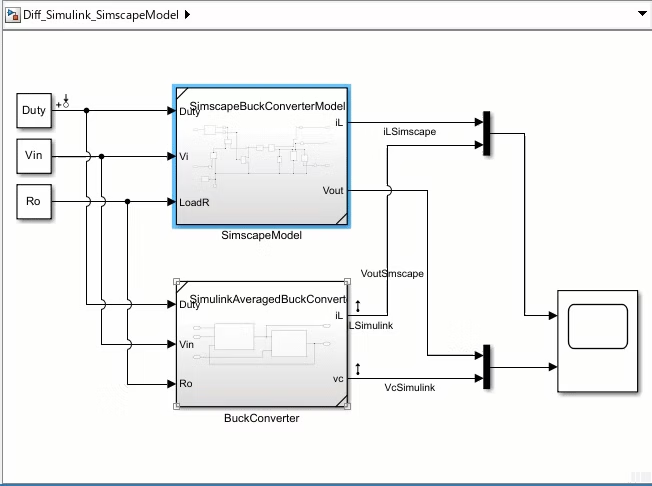

2つのサブシステムを用意して、

- 上はSimscapeのバックコンバータ回路モデル

- 下はSimulinkの状態平均化モデル

というように一つのモデルファイル内で用意した。

両者には共通の入力が定義されているため、両者の粒度やパラメータ影響度に違いがなければ

両モデルの出力は一致するはずである。

**このような検討方法はBuck-to-Buck Testと呼ばれるもので、**

**おもにモデルから自動生成されたCコードの実行結果と、**

**生成元のモデル実行結果を比較することでコード生成結果の妥当性を検証する場面でよく使われる手法である。**

**今回の例はBuck-to-Buck Testが一般的に利用されるソフトウェア設計領域とは異なるが、**

**異なる抽象度のモデルを比較するというBuck to Buck Testの考え方が物理モデリングの検証にも一部活用できることを示す。**

## 1.パラメータの設定

パラメータは下記のように設定する。

Simscape側には直流抵抗成分 ESRやインダクタンスの直流抵抗成分などの要素を追加してモデリングしてみたので

そのパラメータも含まれている。

C1 = 300e-6;%[F]
esr = 1e-4;%[Ohm]

L1 = 200e-6;%[H]
l1r =1e-4; %[Ohm]

fsw = 20000;%{Hz]
Tsw = 1 / fsw;%[Sec]

HighVth = 10;
LowVth = 10;

Ro = 5;
Vin = 12;
Duty = 0.5;


## 2.シミュレーションを実行してスイッチングモデルと平均化モデルの挙動比較

このパラメータでモデルをMATLABからキックして動かす。

このスクリプトでは2つのモデルの出力を比較してみた。

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


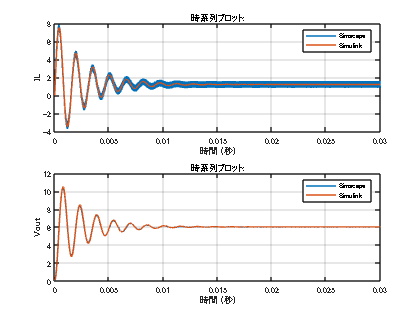

for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

上がコイル電流、下が出力電圧になっているが、わりと一致しているようにみえる。

上のグラフを拡大すると

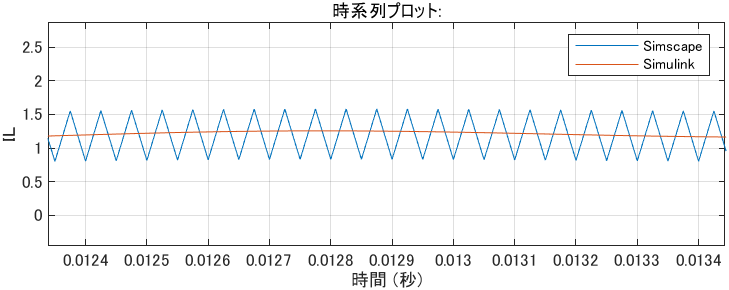

SimscapeはちゃんとPWMでスイッチングしているのでリップルがあるが

Simulinkは平均化されているのでリップルがない

でも平均値としては一致した応答になっているのもわかる。

この場合では両モデルの抽象度やパラメータが一致しており、

制御設計においてSimulinkモデルをベースに設計したとしても差し支えないと考えることができる。

## 3.パラメータを更新して再度シミュレーション(実回路の寄生成分の影響）

次はあえてパラメータによって両者のモデル挙動に変化がある例を示す。

このように一致しない結果を得た場合はSimulinkを扱う制御設計者は回路設計者とその違いの原因について議論することで

両者の共通見解としての原因を明らかにし、その違いを許容するか、設計に反映させるかを判断しなければならない。

このような比較ができる環境がその判断を助ける情報を提供してくれる。

コンデンサの直流抵抗成分:esr

インダクタの直流抵抗成分:l1r

を増加した際の応答を比較する。

これらのパラメータは実際の回路には必ず存在する要素だが

今回あえてSimulink側の微分方程式には定義しなかった。

そのため、理想となる理論式と実際の回路には差異があることが確認できる。

**ここで、理論と実際の結果の違いを鑑みて、**

**モデルに対してどこまでの要素を含めるのが妥当なのかを判断することが大切である。**

esr = 1e-1;%[Ohm]
l1r = 1e-2; %[Ohm]

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


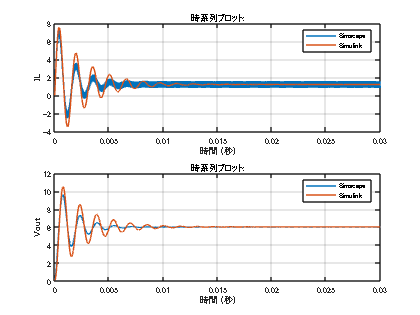

figure;
for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

このグラフからESRやインダクタの直流抵抗成分が振動減衰性に依存していることがうかがえる。

このようなパラメータの影響度を考えると、ESRやインダクタの直流抵抗がそれなりに存在し、無視できない場合は

Simulinkで構築した状態平均化モデルをこれらのパラメータを含めた形で立て直すか、

Simulinkの状態平均化モデルで補償器の構成（たとえばPIで構築するか、Type2補償器なのか、Type3なのか）を決定し、

パラメータの微調整をSimscapeモデルで行うといった手法が考えられる。

このように、結果が不一致となった場合でも作成したモデルはそれぞれ無駄になることはなく、

設計の指標を考える足がかりとして活用することができる。

また、前述した通り、数式ベース、回路ベースのモデルを同一環境で比較できるので、

制御担当者と回路担当者間で共通した議論の土台としてこのモデル環境が有効になる。

そのため　複数のエンジニアで協力して遂行するプロジェクトにおいて　このような比較検討のためのモデル環境が有効であると考える。

#### 3.1  周波数スイープによるSimscapeモデルに対する伝達関数推定

今回はステップ応答で周波数特性の変化を観測したが、ボード線図上でその特性の違いを確認したい。

Simulinkでモデリングされた数式モデルはScript03で示されたような線形化によって伝達関数を取得することができる。

一方でSimscapeは電気回路モデルであるため、数式としてモデリングされていないため、別の手法が必要になる。

これはシミュレータの回路定式化の手法がSimulikとSimscapeで異なっているためである。

これまで述べてきたように状態平均化法によってSimulinkのモデルはPWM1周期分の振る舞いが平均化されて

「微分方程式としてモデリング」されるため、定常状態近傍での偏微分演算が可能になるため、線形化が可能である。

一方　Simscape側ではデバイスのPWMスイッチングの振る舞いを精度良く表現できるように、修正接点解析法を用いている。[4]

PWMによって時間的にONとOFFを繰り返す非線形なモデルは偏微分によって線形化できないため、

外部から正弦波信号を入力した際の出力応答の振幅、および位相変化に基づいて「周波数特性を推定する」という手法を用いる。

## Simulink モデルのモデル操作点での周波数特性の推定

[https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html](https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html)

#### **操作１：伝達関数における入力を指定する。**

１．Dutyが入力されている信号線を右クリックし右クリックメニューを開く

## 4.パラメータを更新して再度シミュレーション(電流不連続モードの存在）

ここではわざと状態平均化法の前提を崩すような回路を作って

今回作成した状態平均化モデルが有効でないケースの存在を明らかにする。

コンバータには電流連続モード、電流不連続モードという回路動作モードがある。

このモードは互いに伝達関数が異なる。[1]

この回路はHighサイドとLowサイドが相補にスイッチングするようにモデリングされているため、

電流の逆流が許容されるため、常に連続モードで動作する。

今回はLowサイドのMOSFETゲートしきい値電圧を意図的に引き上げて

ボディダイオードだけが動作するようにする。すると回路動作が電流不連続モードとなり

電流連続モードを前提としたSimulinkモデルとの不一致が確認できる。

LowVth = 20;

Simdata = sim("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");


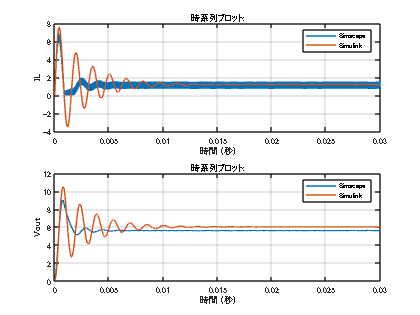

figure;
for i = 1:2
    subplot(2,1,i)
    Simdata.ScopeData{i}.Values.plot()
    grid on;
end
subplot(2,1,1)
ylabel('IL')
legend('Simscape','Simulink');
subplot(2,1,2)
legend('Simscape','Simulink');
ylabel('Vout')

想定通り全く一致していない。

一致してない部分のうちコイル電流部分だけクローズアップしてみると

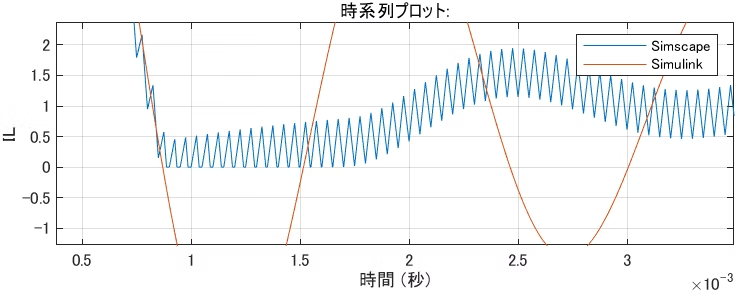

たしかに電流が0で底打ちになっていて逆流していないので

ダイナミクスが切り替わっている事がわかる。

#### 不連続モードのときは状態平均化モデルは使えないのだろうか？

そんなことはない。

連続モードの状態平均化モデルはそのまま使えないのですが

このような違いはすでに議論をされていて、参考文献[1]では不連続モードを

- ターンオン期間

- ターンオフ期間

- ターンオフかつ電流も０で底打ちしてる期間

の３状態で分離して計算し３つを各Duty比で重み付けしたらちゃんと不連続モードで状態平均化モデルを作れることが述べられている。

## まとめ

このサンプルでは１～４を通じて理論ベースの数式とブロック線図モデル、そしてSimscapeを用いた回路モデルを作成し、

その一致性を確認することを述べてきた。

同じコンバータの動作を示す一見”同じ”モデルである一方、それぞれのモデルには特徴があり

それらの特徴をうまく活用すれば理論から回路シミュレーションまで一貫してつながった設計が可能であることを示した。

このような設計を助けるツールとしてMathWorksツールを活用いただければ幸いである。

## Reference

[1] 阿部　征哉, 財津　俊行, 上松 武.　デジタル電源の基礎と設計法 -スイッチング電源のデジタル制御-. 科学情報出版株式会社, 2020,246p, ISBN978-4-904774-84-7.

[2] Frede Blaabjerg, ed. Yanfelng Shen, Zian Qi and Huai Wang. Control of Power Electronic Converters And Systems. Volume 1, Chapter 3 "Modeling and Control of DC-DC Converters" p69-p92, Academic Press, 2018, ISBN 978-0-12-804254-7.

[3] コンバータ制御設計に役立つ状態平均化モデルをsimulinkで書いてみた4 [https://qiita.com/griffin921/items/87dcda9ba1879cca1181](https://qiita.com/griffin921/items/87dcda9ba1879cca1181)

[4][パワーエレクトロニクスシステムの複合的モデリングとシミュレーション技術調査専門委員会](http://www2.iee.or.jp/~dspc/PESim/index.html) **パワエレシミュレーション（PE-Sim）において使用されるシミュレータの特徴一覧表 **[http://www2.iee.or.jp/~dspc/PESim/simulators.html](http://www2.iee.or.jp/~dspc/PESim/simulators.html)